# Ch 3 In Class Practice

## Bungee Jumper Function

velocity1(0.01,0,10,0)

ans = 49.4317

## Bouncing Ball

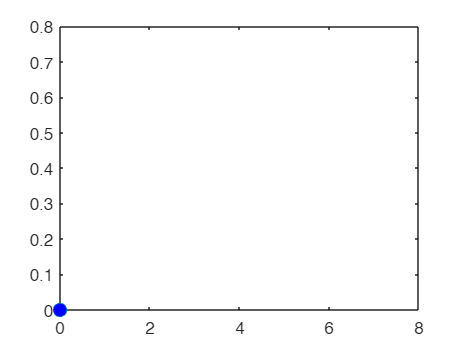

%Problem 3.21 & 2.
maxit=1000;
g=9.81; theta0=50*pi/180; v0=5; CR=0.83;
j=1;t(j)=0;x=0;y=0;

xx=x;yy=y;
plot(x,y,'o','MarkerFaceColor','b','MarkerSize',8)
xmax=8; axis([0 xmax 0 0.8])
M(1)=getframe;

dt=1/128;
j=1; xxx=0; iter=0;

while(1)
    tt=0;
    timpact=2*v0*sin(theta0)/g;
    ximpact=v0*cos(theta0)*timpact;
    
    while(1)
        j=j+1;
        h=dt;
        if tt+h>timpact,h=timpact-tt;end
        t(j)=t(j-1)+h;
        tt=tt+h;
        x=xxx+v0*cos(theta0)*tt;
        y=v0*sin(theta0)*tt-0.5*g*tt^2;
        xx=[xx x];yy=[yy y];
        plot(xx,yy,':',x,y,'o','MarkerFaceColor','b','MarkerSize',8)
        axis([0 xmax 0 0.8])
        M(j)=getframe;
        iter=iter+1;
        if tt>=timpact, break, end
    end
    v0=CR*v0;
    xxx=x;
    if x>=xmax|iter>=maxit,break,end
end
pause
clf
axis([0 xmax 0 0.8])
movie(M,1,36)

## Problem 3.22

Animation stuff

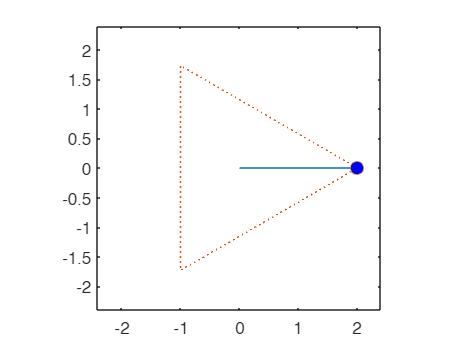

r = 2; nt = 3; nm = 2;
phasor(r, nt, nm); % animation, takes forever to load

## Problem 3.2 - Future Worth

F = P(1+i)^n

Calc the future worth of an investment for each year from 1-n. 

Input: P, i, n.

Output: table w/ headings and columns for n & F

% See function file
P = 100*10^3; i = 0.05; n = 10;
futureWorthP3_2(P, i, n)


 Year 	Future Worth:
    0         100000
    1         105000
    2         110250
    3         115763
    4         121551
    5         127628
    6         134010
    7         140710
    8         147746
    9         155133
   10         162889


## Problem 3.8

Develop M file ftn that gets grade from 0 to 100, returns a letter grade according to the typical scheme. Terminates if <0 or >100

score = 89.999;
grade = lettergrade(score)

grade = 'B'


score = 70;
grade = lettergrade(score)

grade = 'C'

## Problem 3.11

Hollow horiz cylinder. Has volume V in the cylinder w/ liquid. Make a .m file to create a plot of volume versus depth.

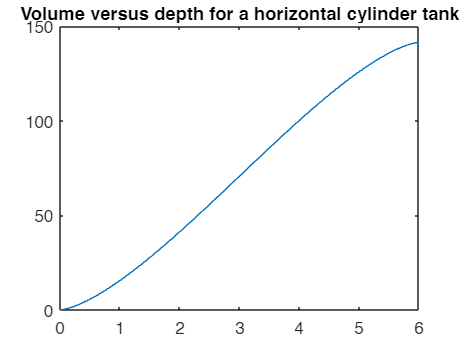

r = 3; L = 5; plot_title = 'Volume versus depth for a horizontal cylinder tank';
cylinder(r,L,plot_title);

## In-Class

*Piecewise Functions *are sometimes useful when the relationship between a dependent and an independent variable cannot be adequately represented by a single equation. For example, the velocity of a rocket might be described by

Develop an M-file function to compute *v* as a function of t. What is the velocity when t = 4 & t=37.5? 

velo_4 = rocketVelo(4)

velo_4 = 140

velo_375 = rocketVelo(37.5)

velo_375 = 676.3361